## Ali Saeizadeh - 810196477

## Section 1

### 1.

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab5'
clear all; clc; close all;
dcl_init;
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k)

b_tx =      0     0
     1     1
     0     0
     0     0
     0     1
     0     1
     0     1
     0     0
     0     0
     1     0


### 2.

flg_gray_encode = 1

flg_gray_encode = 1

if(flg_gray_encode == 1)
    b_code = gray_code(k)    
else
    b_code = non_code(k) 
end 

b_code =      0     0
     0     1
     1     1
     1     0



sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
sym_idx

sym_idx =      1
     3
     1
     1
     2
     2
     2
     1
     1
     4


[cons, Es_avg] = constellation(M, modulation)

cons =    1.0000 + 0.0000i
   0.0000 + 1.0000i
  -1.0000 + 0.0000i
  -0.0000 - 1.0000i


Es_avg = 1

mod_sym = zeros(size(sym_idx));
for i=1:size(sym_idx,1)
    mod_sym(i,1) = cons(sym_idx(i,1));
end
mod_sym

mod_sym =    1.0000 + 0.0000i
  -1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 + 1.0000i
   0.0000 + 1.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
  -0.0000 - 1.0000i


### 3

pulse_shape_mode = 'kron'

pulse_shape_mode = 'kron'

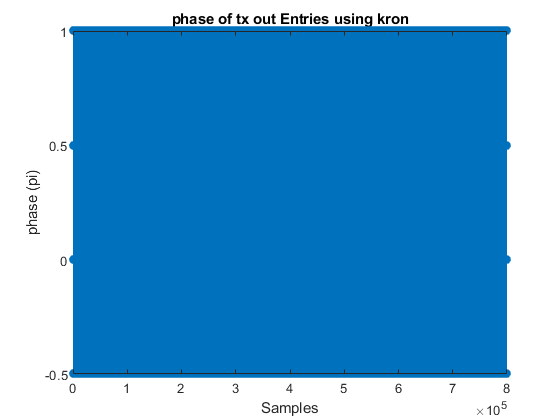

[tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
stem(angle(tx_smpl)/pi, 'filled')
title('phase of tx out Entries using kron')
xlabel('Samples')
ylabel('phase (pi)')

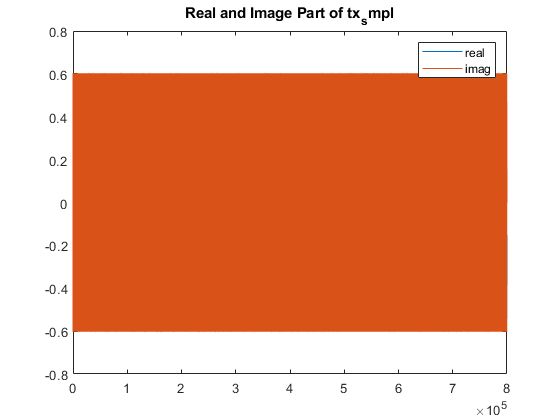


plot([real(tx_smpl), imag(tx_smpl)])
title('Real and Image Part of tx_smpl')
legend('real','imag')

pulse_shape_mode = 'conv'

pulse_shape_mode = 'conv'

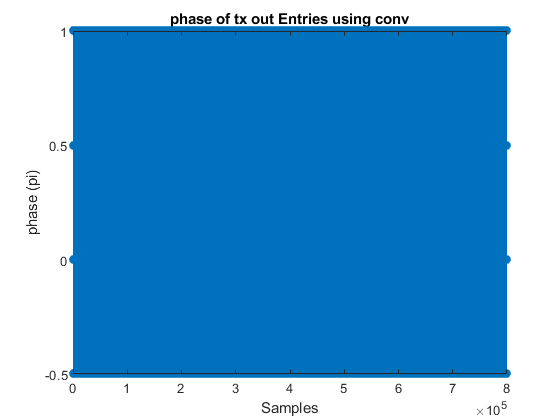

[tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
stem(angle(tx_smpl)/pi, 'filled')
title('phase of tx out Entries using conv')
xlabel('Samples')
ylabel('phase (pi)')


plot([real(tx_smpl), imag(tx_smpl)])
title('Real and Image Part of tx_smpl')
legend('real','imag')

tx_smpl_delayed = [zeros(chnl_delay_in_smpl,1); tx_smpl];
rx_smpl = tx_smpl_delayed .* exp(1i*chnl_phase_offset);

Eb =  Es_avg/log2(M) 

Eb = 0.5000

EbNo = db2pow(snr_max)

EbNo = 10

var_noise = (Eb ./ EbNo)

var_noise = 0.0500

mean_noise = 0

mean_noise = 0

noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise

noise_smpl =    0.0869 + 0.1453i
   0.2025 + 0.0202i
   0.0870 + 0.0376i
   0.0918 + 0.0589i
   0.1214 + 0.0446i
   0.0129 - 0.0365i
  -0.0629 + 0.2009i
   0.0052 + 0.0545i
  -0.1422 + 0.0013i
  -0.0103 - 0.0334i


rx_smpl_noise = rx_smpl + noise_smpl

rx_smpl_noise =    0.0869 + 0.1453i
   0.3533 + 0.0202i
   0.3885 + 0.0376i
   0.5440 + 0.0589i
   0.7245 + 0.0446i
   0.4652 - 0.0365i
   0.2386 + 0.2009i
   0.1560 + 0.0545i
  -0.1422 + 0.0013i
  -0.1611 - 0.0334i


rx_smpl_eq = rx_smpl_noise(chnl_delay_in_smpl + 1 : end);
modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode

modulation = 'psk'

M = 4

fs = 10000000

smpl_per_symbl = 8

pulse_name = 'triangular'

rx_mode = 'matched_filter'

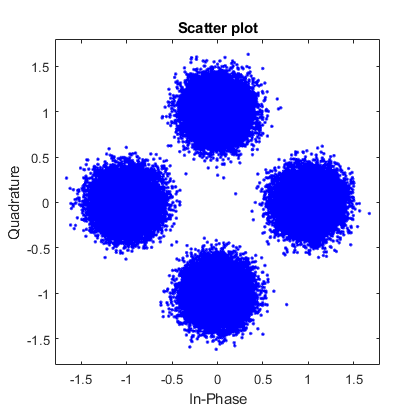

[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
scatterplot(rx_sym)

det_bit = b_code(det_sym_idx,:)

det_bit =      0     0
     1     1
     0     0
     0     0
     0     1
     0     1
     0     1
     0     0
     0     0
     1     0


ser = sum(det_sym_idx ~= sym_idx)/length(sym_idx)

ser = 1.0000e-05

ber = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2))

ber = 5.0000e-06

serPSK = zeros(size(snr_db));
berPSK = zeros(size(snr_db));
for i = 0:1:3
    Eb =  Es_avg/log2(M);
    EbNo = db2pow(i);
    var_noise = (Eb ./ EbNo);
    mean_noise = 0;
    noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
    rx_smpl_noise = rx_smpl + noise_smpl;
    rx_smpl_eq = rx_smpl_noise(chnl_delay_in_smpl + 1 : end);
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
    det_bit = b_code(det_sym_idx,:);
    serPSK(i + 1) = sum(det_sym_idx ~= sym_idx)/length(sym_idx);
    berPSK(i + 1) = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2));
end


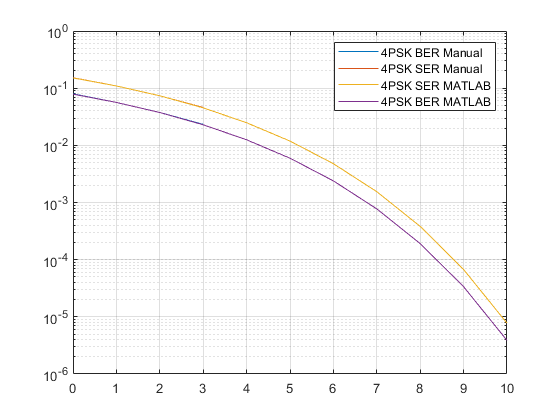

figure
[berPSK_matlab, serPSK_matlab] = berawgn(snr_db,modulation,M,'nondiff');
semilogy(snr_db,berPSK)
hold on
semilogy(snr_db,serPSK)
hold on
semilogy(snr_db,serPSK_matlab)
hold on
semilogy(snr_db,berPSK_matlab)
legend('4PSK BER Manual','4PSK SER Manual', '4PSK SER MATLAB', '4PSK BER MATLAB')
grid on

figure

## Time Delay Effect

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab5'
clear all; clc; close all;
dcl_init;
modulation = 'psk';             
k = 2;
M = 2^k; 
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k);
flg_gray_encode = 1

flg_gray_encode = 1

if(flg_gray_encode == 1);
    b_code = gray_code(k)  ;  
else
    b_code = non_code(k) ;
end 
sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
[cons, Es_avg] = constellation(M, modulation);
mod_sym = zeros(size(sym_idx));
for i=1:size(sym_idx,1)
    mod_sym(i,1) = cons(sym_idx(i,1));
end
pulse_shape_mode = 'kron';
[tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);

EbNo = db2pow(snr_max)

EbNo = 10

delays_c = round([0, 0.1, 0.5, 0.8] * smpl_per_symbl)

delays_c =      0     1     4     6


chnl_delay_in_smpl = 0

chnl_delay_in_smpl = 1

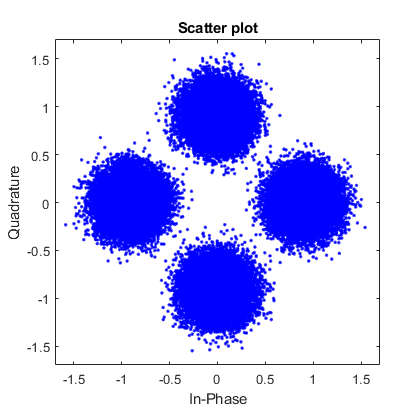

chnl_delay_in_smpl = 4

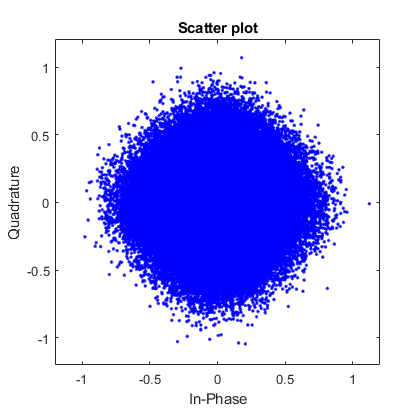

chnl_delay_in_smpl = 6

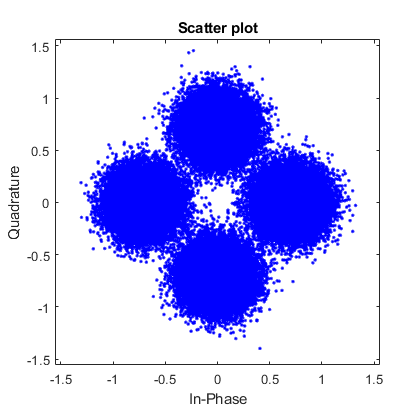

ser = zeros(length(delays_c),1);
ber = zeros(length(delays_c),1);
for i = 1:length(delays_c)
    figure
    chnl_delay_in_smpl = delays_c(i)
    tx_smpl_delayed = [zeros(chnl_delay_in_smpl,1); tx_smpl];
    tx_smpl_delayed = tx_smpl_delayed(1:length(tx_smpl));
    rx_smpl = tx_smpl_delayed .* exp(1i*chnl_phase_offset);
    Eb =  Es_avg/log2(M) ;
    EbNo = db2pow(snr_max);
    var_noise = (Eb ./ EbNo);
    mean_noise = 0;
    noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
    rx_smpl_noise = rx_smpl + noise_smpl;
    rx_smpl_eq = rx_smpl_noise;
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
    scatterplot(rx_sym)
    det_bit = b_code(det_sym_idx,:);
    ser(i) = sum(det_sym_idx ~= sym_idx)/length(sym_idx);
    ber(i) = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2));
end

ber 

ber =     0.0000
    0.0000
    0.2618
    0.5018


ser

ser =     0.0000
    0.0001
    0.4541
    0.7521


As we can see in figures our constellation is ruined because of time delay.

Also we have much worse bit error and symbol error when we have time delay.

time delay = 0 ----> ber = 0, ser = 0

time delay = 0.1 ----> ber = 0, ser = 0.0001

time delay = 0.5 ----> ber = 0.26, ser = 0.45

time delay = 0.8 ----> ber = 5, ser = 0.7521

## Time Delay Compensation

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab5'
clear all; clc; close all;
dcl_init;
modulation = 'psk';             
k = 2;
M = 2^k; 
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k);

hdr_bit = repmat(reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958DC5']'))', [], 1),1,k)

hdr_bit =      1     1
     0     0
     0     0
     0     0
     0     0
     0     0
     1     1
     1     1
     0     0
     1     1


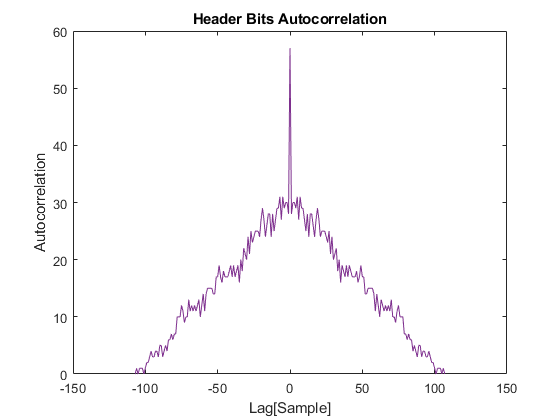

[corr_out_rx, lag] = xcorr(hdr_bit);
plot(lag, corr_out_rx);
xlabel('Lag[Sample]')
ylabel('Autocorrelation')
title('Header Bits Autocorrelation')

[corr_out_rx_max, idx_max] = max(corr_out_rx)

corr_out_rx_max =     57    57    57    57


idx_max =    108   108   108   108


b_tx = [hdr_bit; b_tx];

flg_gray_encode = 1

flg_gray_encode = 1

if(flg_gray_encode == 1);
    b_code = gray_code(k)  ;  
else
    b_code = non_code(k) ;
end 
sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
[cons, Es_avg] = constellation(M, modulation);
mod_sym = zeros(size(sym_idx));
for i=1:size(sym_idx,1)
    mod_sym(i,1) = cons(sym_idx(i,1));
end
pulse_shape_mode = 'kron';
[tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
hdr_smpl = tx_smpl(1:length(hdr_bit) * smpl_per_symbl)

hdr_smpl =    0.0000 + 0.0000i
  -0.1508 + 0.0000i
  -0.3015 + 0.0000i
  -0.4523 + 0.0000i
  -0.6030 + 0.0000i
  -0.4523 + 0.0000i
  -0.3015 + 0.0000i
  -0.1508 + 0.0000i
   0.0000 + 0.0000i
   0.1508 + 0.0000i


delays_c = round([0, 0.1, 0.5, 0.8] * smpl_per_symbl)

delays_c =      0     1     4     6


ser = zeros(length(delays_c),1);
ber = zeros(length(delays_c),1);
for i = 1:length(delays_c)
    figure
    chnl_delay_in_smpl = delays_c(i)
    tx_smpl_delayed = [zeros(chnl_delay_in_smpl,1); tx_smpl];
%   tx_smpl_delayed = tx_smpl_delayed(1:length(tx_smpl))
    rx_smpl = tx_smpl_delayed .* exp(1i*chnl_phase_offset);
    Eb =  Es_avg/log2(M) ;
    EbNo = db2pow(snr_max);
    var_noise = (Eb ./ EbNo);
    mean_noise = 0;
    noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
    rx_smpl_noise = rx_smpl + noise_smpl;
    
    rx_smpl_eq = rx_smpl_noise;
    [r,lag] = xcorr(rx_smpl_eq, hdr_smpl);
    [corr_out_rx_max, idx_max] = max(r)
    estimated_time_delay = lag(idx_max)
    rx_smpl_eq = rx_smpl_eq(estimated_time_delay + 1:end);
    
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
%     scatterplot(rx_sym);
    det_bit = b_code(det_sym_idx,:);
    ser(i) = sum(det_sym_idx ~= sym_idx)/length(sym_idx);
    ber(i) = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2));
end

chnl_delay_in_smpl = 0

corr_out_rx_max = 1.0822e+02 - 5.8222e-01i

idx_max = 800864

estimated_time_delay = 0

chnl_delay_in_smpl = 1

corr_out_rx_max = 1.0551e+02 + 3.3236e-01i

idx_max = 800866

estimated_time_delay = 1

chnl_delay_in_smpl = 4

corr_out_rx_max = 1.0692e+02 - 3.1900e+00i

idx_max = 800872

estimated_time_delay = 4

chnl_delay_in_smpl = 6

corr_out_rx_max = 1.1157e+02 - 4.3707e-01i

idx_max = 800876

estimated_time_delay = 6

ber

ber = 	1.0e+-5 *

    0.9989
         0
    0.4995
         0


ser

ser = 	1.0e+-4 *

    0.1998
         0
    0.0999
         0


By adding header in the beginenning of the TX bit, now we're able to estimate time delay by using cross correlation of the header.

In all  cases, our estimation of time delay is accurate and bit and symbol error is decreased to zero time delay value.

time dealy = 0 ---> ber =    9.9892e-06 , ser =    1.9978e-05

time dealy = 0.1 ---> ber = 0, ser = 0

time dealy = 0.5 ---> ber =    4.9946e-06, ser =    9.9892e-06

time dealy = 0.8 ---> ber = 0, ser = 0

## Phase Offset Effect

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab5'
clear all; clc; close all;
dcl_init;
modulation = 'psk';             % Modulation Name ('psk', 'pam', 'qam', 'fsk')
k = 2;                          % Bit Per Symbol
M = 2^k; 
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k);
flg_gray_encode = 1

flg_gray_encode = 1

if(flg_gray_encode == 1);
    b_code = gray_code(k)  ;  
else
    b_code = non_code(k) ;
end 
sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
[cons, Es_avg] = constellation(M, modulation);
mod_sym = zeros(size(sym_idx));
for i=1:size(sym_idx,1)
    mod_sym(i,1) = cons(sym_idx(i,1));
end
pulse_shape_mode = 'kron';
[tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
EbNo = db2pow(snr_max)

EbNo = 10

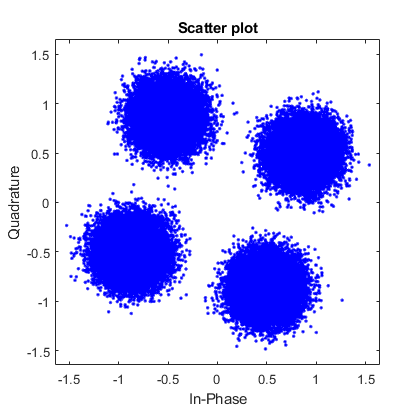

chnl_phase_offset = pi/6;
rx_smpl = tx_smpl .* exp(1i*chnl_phase_offset);
Eb =  Es_avg/log2(M) ;
EbNo = db2pow(snr_max);
var_noise = (Eb ./ EbNo);
mean_noise = 0;
noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
rx_smpl_noise = rx_smpl + noise_smpl;
rx_smpl_eq = rx_smpl_noise;
[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
scatterplot(rx_sym)

det_bit = b_code(det_sym_idx,:);
ser = sum(det_sym_idx ~= sym_idx)/length(sym_idx)

ser = 0.0522

ber = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2))

ber = 0.0261

We can see that the constellation is rotated by value of phase offset. (all points is multiplied by $e^{i \phi}$)

##  Phase Offser Compensation

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab5'
clear all; clc; close all;
dcl_init;
modulation = 'psk';             % Modulation Name ('psk', 'pam', 'qam', 'fsk')
k = 2;                          % Bit Per Symbol
M = 2^k; 
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k);
%Making header
hdr_bit = repmat(reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958DC5']))', [], 1),1,k)

hdr_bit =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


b_tx = [hdr_bit; b_tx];

flg_gray_encode = 1

flg_gray_encode = 1

if(flg_gray_encode == 1)
    b_code = gray_code(k)  ;  
else
    b_code = non_code(k) ;
end 
sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
[cons, Es_avg] = constellation(M, modulation);
mod_sym = zeros(size(sym_idx));
for i=1:size(sym_idx,1)
    mod_sym(i,1) = cons(sym_idx(i,1));
end
pulse_shape_mode = 'kron';
[tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);

hdr_smpl = tx_smpl(1:length(hdr_bit) * smpl_per_symbl)

hdr_smpl =    0.0000 + 0.0000i
   0.1508 + 0.0000i
   0.3015 + 0.0000i
   0.4523 + 0.0000i
   0.6030 + 0.0000i
   0.4523 + 0.0000i
   0.3015 + 0.0000i
   0.1508 + 0.0000i
   0.0000 + 0.0000i
   0.1508 + 0.0000i



EbNo = db2pow(snr_max)

EbNo = 10

phase_offset = [0, pi/6]

phase_offset =          0    0.5236


corr_out_rx_max = 1.0616e+02 - 1.9732e-01i

idx_max = 800848

estimated_time_delay = 4

estimated_phase_offset = -0.0019

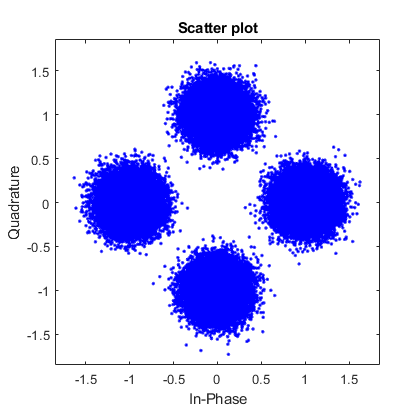

corr_out_rx_max = 90.5334 + 49.4227i

idx_max = 800848

estimated_time_delay = 4

estimated_phase_offset = 0.4997

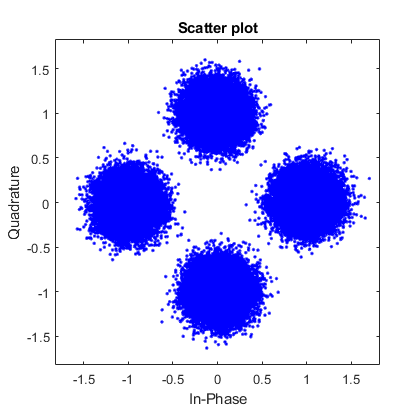

ser = zeros(length(phase_offset),1);
ber = zeros(length(phase_offset),1);
for i = 1:length(phase_offset)
    chnl_delay_in_smpl = 4;
    chnl_phase_offset = phase_offset(i);
    tx_smpl_delayed = [zeros(chnl_delay_in_smpl,1); tx_smpl];
    rx_smpl = tx_smpl_delayed .* exp(1i*chnl_phase_offset);
    
    Eb =  Es_avg/log2(M) ;
    EbNo = db2pow(snr_max);
    var_noise = (Eb ./ EbNo);
    mean_noise = 0;
    noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
    rx_smpl_noise = rx_smpl + noise_smpl;
    rx_smpl_eq = rx_smpl_noise;
    
    [r,lag] = xcorr(rx_smpl_eq, hdr_smpl);
    [corr_out_rx_max, idx_max] = max(r)
    estimated_time_delay = lag(idx_max)
    rx_smpl_eq = rx_smpl_eq(estimated_time_delay + 1:end);
    estimated_phase_offset = angle(corr_out_rx_max)
    rx_smpl_eq = rx_smpl_eq .* exp(-1i*estimated_phase_offset);
    
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
    scatterplot(rx_sym)
    det_bit = b_code(det_sym_idx,:);
    ser(i) = sum(det_sym_idx ~= sym_idx)/length(sym_idx);
    ber(i) = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2));
end

ser 

ser = 	1.0e+-5 *

    0.9990
         0


ber

ber = 	1.0e+-5 *

    0.4995
         0


In this section we have both phase offset and time delay. both of them have been compensated by using cross correlation of header which is known by reciever and transmitter.

 Phase offset is estimated by angle of maximum of correlation and its not accurate but it's value is close to real one.

phase offset = 0, time delay = 0.5 ---- > ber =    4.9948e-06   , ser = 9.9895e-06

phase offset = 30 deg , time delay = 0.5 ---- > ber = 0 , ser = 0